%%
% 5281873
clc
close all
clear 

% setup
a = 5; b = 8; c = 3;

NCS.A = [a-b 0.5-c;
         0   1];

NCS.B = [0; 1];

NCS.nx = 2;

NCS.K = [-2 1.6];
% NCS.K = [-2 0];

NCS.h = 0.2;

%% 5.1
syms sigma

cvx_clear
cvx_begin sdp

    variable P(2,2) semidefinite
    variable Q(2,2) semidefinite

    subject to

        % (A-B*K)'*P*(A-B*K)-P <= 0.001*eye(2)

        (NCS.A - NCS.B*NCS.K)' * P + P*(NCS.A - NCS.B*NCS.K) <= -Q;
        Q >= 10* eye(NCS.nx); 

cvx_end

 
Calling SDPT3 4.0: 12 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  =  8,   num. of sdp  blk  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.7e+00|2.8e+01|1.3e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.886|1.6e-06|3.3e+00|2.0e+02| 0.000000e+00 -9.540688e+00| 0:0:00| chol  1  1 
 2|1.000|0.991|9.0e-07|4.1e-02|2.4e+00| 0.000000e+00 -1.001207e-01| 0:0:00| chol  1  1 
 3|1.000|1.000|1.1e-07|1.0e-03|5.3e-02| 0.000000e+00 -4.986991e-04| 0:0:00| chol  1  1 
 4|1.000|1.000|4.2e-09|1.0e-04|4.1e-03|


NCS_ETC.P = P;
Q

Q =    14.8517    0.1194
    0.1194   15.1516





phi = [NCS.A'*P + P*NCS.A + sigma*Q , -P*NCS.B*NCS.K;
       -(NCS.B*NCS.K)'*P            , zeros(2,2)];
NCS_ETC.phi = vpa(phi,4);
NCS_ETC.phi

 
ans =
 
        [-38.73 + 14.85 sigma , -21.30 + 0.1194 sigma , 5.160 , -4.128]
        [                                                             ]
        [-21.30 + 0.1194 sigma ,  12.55 + 15.15 sigma , 25.45 , -20.36]
        [                                                             ]
        [5.160 ,              25.45 ,              0. ,             0.]
        [                                                             ]
        [-4.128 ,             -20.36 ,             0. ,             0.]



clear phi P

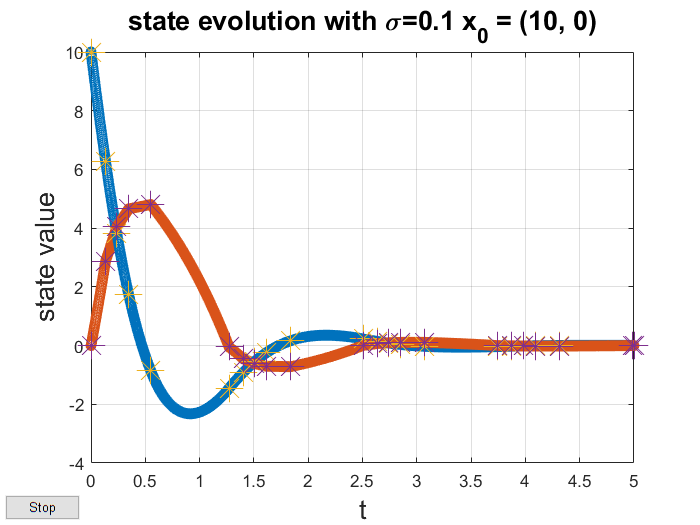

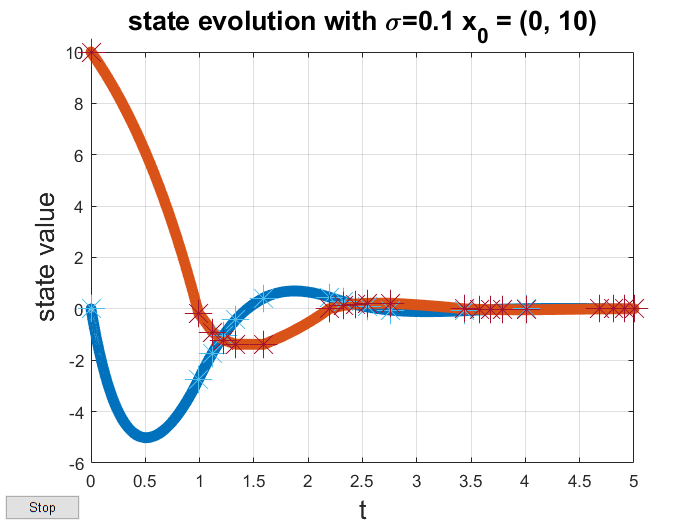

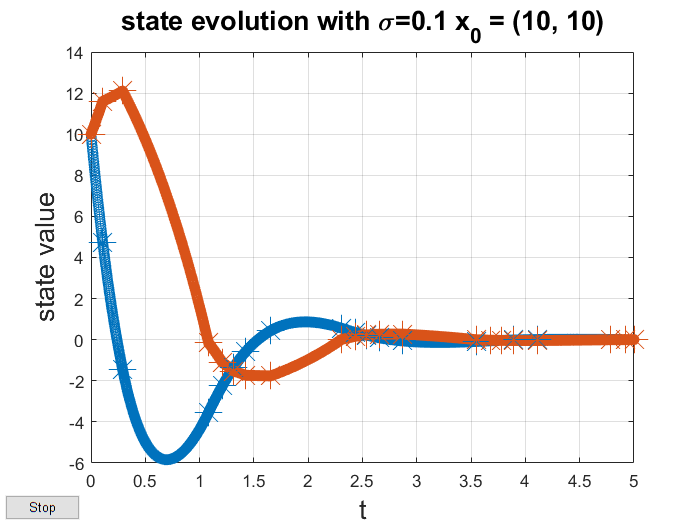

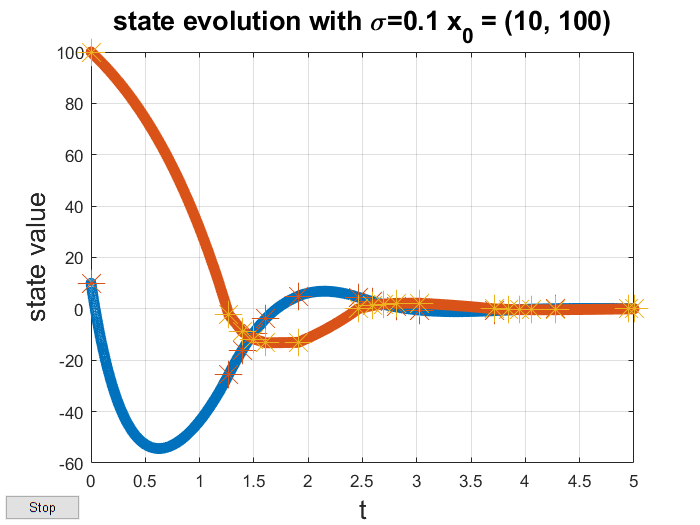

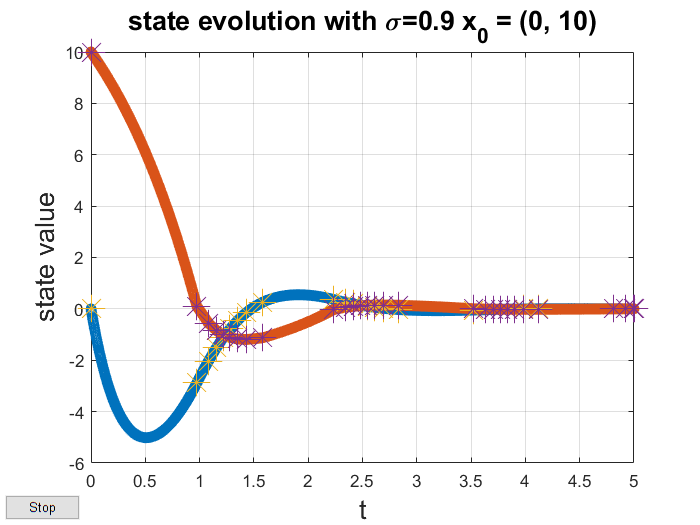

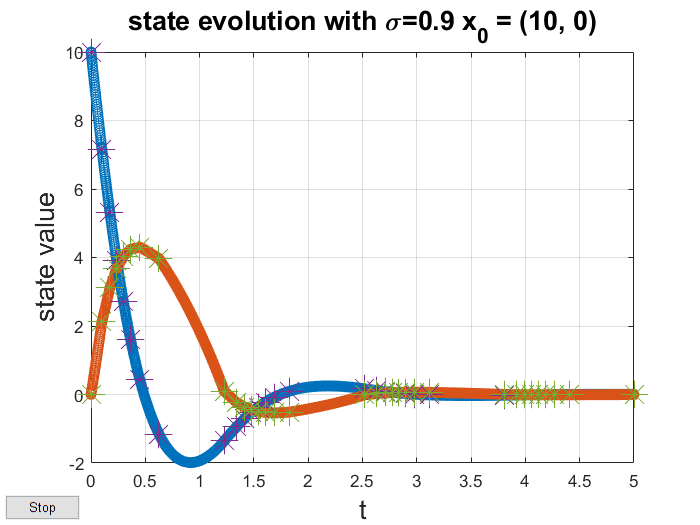

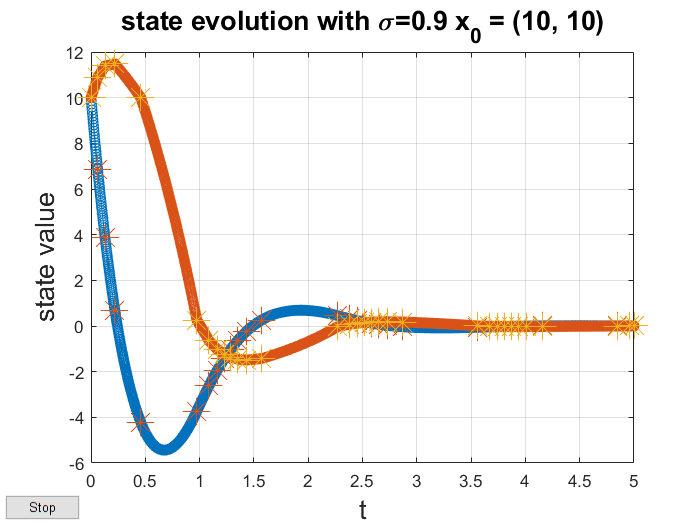

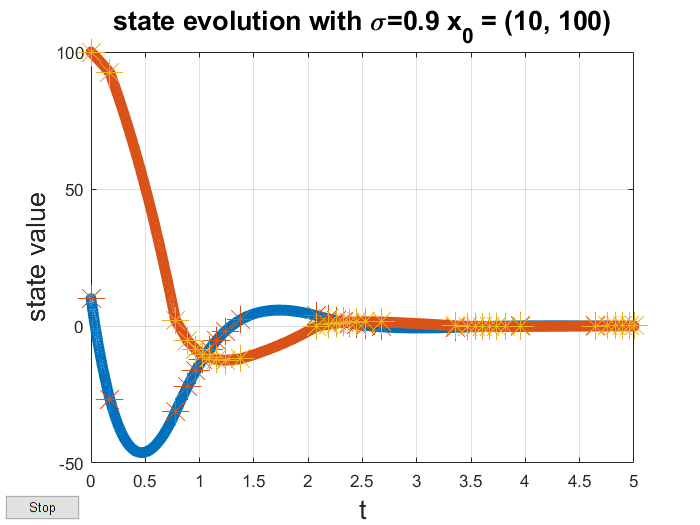

%% 5.2

sigma_samples = 0.1:0.1:0.9;
% x_0_samples = [0,10,10,10,100,100;
%             10,0,10,100,10,100];
x_0_samples = [0, 10, 10, 10;
            10, 0, 10, 100];

for i = 1:1:length(sigma_samples)

    sigma = sigma_samples(i);

    phi = double([NCS.A'*NCS_ETC.P + NCS_ETC.P*NCS.A + sigma*Q, -NCS_ETC.P*NCS.B*NCS.K;
                       -(NCS.B*NCS.K)'*NCS_ETC.P                            , zeros(2,2)]);

    for j = 1:1:size(x_0_samples,2)

        x_sk = x_0_samples(:,j);
        x_0 = x_0_samples(:,j);
    
        timestep = 0;
        x_history = x_sk';
            
        triggered_time = 0; triggered_value = x_sk;

        t_finish = 5; t_current = 0;
        
        figure

        while t_current < t_finish

            options = odeset('Events', @(t, x) ETC_Event_update(t, x, phi, x_sk), 'OutputFcn', @odeplot, 'MaxStep', 1e-2);
        
            [t, x] = ode45(@(t, x) ETC_model(t, x, NCS.A, NCS.B, NCS.K, x_sk), [t_current, t_finish], x_sk, options);
            hold on;
        
            % simulation will stop if the events fulfill
            % we need to record them 
            timestep = [timestep; t(2:end)];
            x_history = [x_history; x(2:end,:)];
        
            t_current = timestep(end);
        
            x_sk = x(end,:)';
        
            triggered_time = [triggered_time, timestep(end)];
            triggered_value = [triggered_value, x(end,:)'];
                   
        end

        plot(triggered_time, triggered_value, '*', 'MarkerSize', 16)
        xlabel('t', 'FontSize', 16)
        ylabel('state value', 'FontSize', 16)
        figure_title = "state evolution with \sigma=" + num2str(sigma) + " "+"x_0 = ("+num2str(x_0(1))+", "+num2str(x_0(2)) + ")";   
        title(figure_title, 'FontSize', 16);
        grid on
        
    end
end


clear i j k

%% 5.3

figure

sigma = 0.3;
phi = double([NCS.A'*NCS_ETC.P + NCS_ETC.P*NCS.A + sigma*Q, -NCS_ETC.P*NCS.B*NCS.K;
                   -(NCS.B*NCS.K)'*NCS_ETC.P                            , zeros(2,2)]);


t_total = 0; total_triggered_times = 0;

initial_conditions = [];


for i = 1:1:200

    t_current = 0;

    x_sk = (rand(2,1)-0.5)*100;

    initial_conditions = [initial_conditions,x_sk];

    timestep = [0];
    x_history = x_sk';

    triggered_time = 0;
    triggered_value = x_sk;

    initial_lyapunov = x_sk'*NCS_ETC.P*x_sk;

    flag = 1;


    while flag == 1
        
        if (t_current > t_finish)
        
            t_finish = t_finish+1;
        
        end

        options = odeset('Events', @(t, x) ETC_Event_update(t, x, phi, x_sk), 'MaxStep', 1e-2);
    
        [t, x] = ode45(@(t, x) ETC_model(t, x, NCS.A, NCS.B, NCS.K, x_sk), [t_current, t_finish], x_sk, options);
    
        % simulation will stop if the events fulfill
        % we need to record them 
        timestep = [timestep; t(2:end)];
        x_history = [x_history; x(2:end,:)];
    
        t_current = timestep(end);
    
        x_sk = x(end,:)';
    
        triggered_time = [triggered_time, timestep(end)];
        triggered_value = [triggered_value, x(end,:)'];

        if (x_sk'*NCS_ETC.P*x_sk - 0.1*initial_lyapunov <= 0)
            t_total = t_current + t_total;
            total_triggered_times = total_triggered_times + length(triggered_time) - 1;
            flag = 0;        
        end
    end
end

h_avg = t_total/total_triggered_times

h_avg = 0.3249

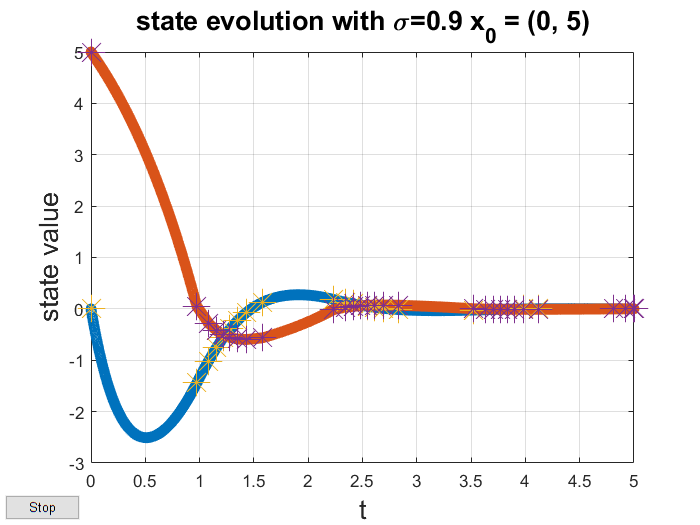

%% 5.4

x_0 = [0; 5];
x_sk = x_0;

timestep = 0;
x_history = x_sk';

triggered_time = 0;
triggered_value = x_sk;

t_finish = 5;
t_current = 0;

figure

while t_current < t_finish

    options = odeset('Events', @(t, x) ETC_Event_update(t, x, phi, x_sk), 'OutputFcn', @odeplot, 'MaxStep', 1e-2);

    [t, x] = ode45(@(t, x) ETC_model(t, x, NCS.A, NCS.B, NCS.K, x_sk), [t_current, t_finish], x_sk, options);
    hold on;

    % simulation will stop if the events fulfill
    % we need to record them 
    timestep = [timestep; t(2:end)];
    x_history = [x_history; x(2:end,:)];

    t_current = timestep(end);

    x_sk = x(end,:)';

    triggered_time = [triggered_time, timestep(end)];
    triggered_value = [triggered_value, x(end,:)'];
           
end

plot(triggered_time, triggered_value, '*', 'MarkerSize', 16)
xlabel('t', 'FontSize', 16)
ylabel('state value', 'FontSize', 16)
figure_title = "state evolution with \sigma=" + num2str(sigma) + " "+"x_0 = ("+num2str(x_0(1))+", "+num2str(x_0(2)) + ")";   
title(figure_title, 'FontSize', 16);
grid on

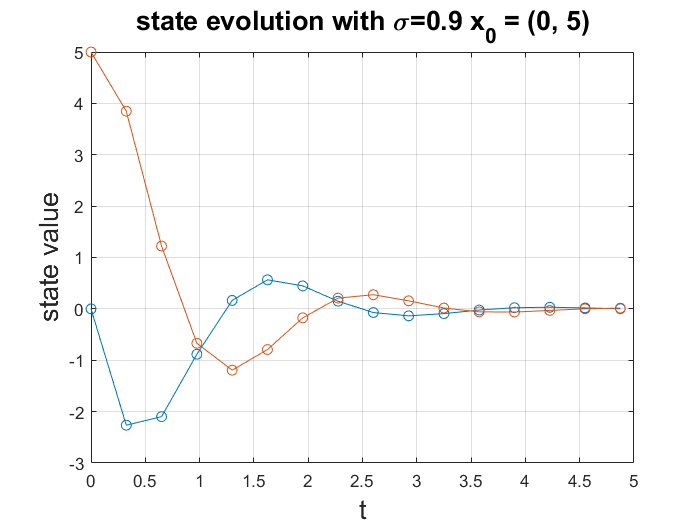


% DTCS
DTCS = c2d(ss(NCS.A, NCS.B, [], []), h_avg);

step = floor(t_finish/h_avg);

A_4 = DTCS.A - DTCS.B * NCS.K;

x_history = x_0;
x_previous = x_0;

for i = 1:1:step

    x_temp = A_4 * x_previous;
    x_history = [x_history, x_temp];
    x_previous = x_temp;

end

figure

plot([0:1:step]*h_avg, x_history, '-o')
grid on;

xlabel('t', 'FontSize', 16)
ylabel('state value', 'FontSize', 16)
figure_title = "state evolution with \sigma=" + num2str(sigma) + " "+"x_0 = ("+num2str(x_0(1))+", "+num2str(x_0(2)) + ")";   
title(figure_title, 'FontSize', 16);



t_total_DTC = 0;

for i = 1:1:200

    x_0 = initial_conditions(:,i);

    x_sk = x_0;
    x_previous = x_sk;
    initial_lyapunov = x_0'*NCS_ETC.P*x_0;

    x_history = [];

    for j = 1:1:step

        x_temp = A_4*x_previous;
        x_history = [x_history,x_temp];
        x_previous = x_temp;
    
        if(x_temp'*NCS_ETC.P*x_temp <= 0.1*initial_lyapunov)
        
            t_total_DTC = t_total_DTC + j*h_avg;

            break;       
        end
    end
end

t_ETC_average = t_total/100

t_ETC_average = 2.3234

t_DTC_average = t_total_DTC/100

t_DTC_average = 2.2551

function dxdt = ETC_model(t,x,A,B,K,x_sk)
    dxdt=A*x-B*K*x_sk;
end

function [convergence, isterminal, direction] = ETC_Event_update(t,x,phi_sample,x_sk)
    convergence=[x',x_sk']*phi_sample*[x;x_sk];
    isterminal = 1; direction = 1;
end
